# EPFL ENV-424 - Water Ressource Engineering Project - Autumn 2022 - Group D

# Plan of a multipurpose reservoir

A reservoir is used for hydroelectrical energy production and flood prevention. You should evaluate the feasibility of improving the flood control operations of an existing reservoir of a hydropower plant. A larger fraction of the storage needs to be reserved for flood control and cannot be used for hydroelectric generation. The downstream part of the river should be protected from floods larger than Q lim . The larger the volume for hydroelectric use, the higher the energy production. The larger the volume for flood control, the more efficiently floods can be attenuated. The two uses (hydroelectric and flood control) are therefore in competition. The goal of the assignment is to estimate the trade off between money earned with energy production and probability that the released flow Q out exceeds Q lim , as a function of the volume reserved for flood control. Note that the discharge used for hydropower generation is then released into a different river system.

`All deliverables can be easily found as they are introduced in this specific font.`

## **Read all input parameters (P, Q, etc.) **

clear 
close all
clc

load data/P.txt
load data/Q_obs.txt
load data/temperature.txt
load data/kc.txt
load data/area_rating_curve.txt %[elevation above sea level, lake area]

## **Setting the parameters **

%hydrological model
sw=0.25;     % wilting point
s1=0.4;      % soil moisture stress threshold
n=0.3;       % porosity
Qb=7;        % m^3/s, baseflow
tsup=22;     % h, mean superficial residence time
A=4000;      % km^2, catchment area
phi=38;      % degree, latitude 

%ARBITRARY VALUES
Ksat=3*10^-6;         %saturated hydraulic conductivity, K(s)=Ksat*s^c [m/s]
c=5;          
tsub=8*24;        %h, mean sub-superficial residence time
z=2;          %m, root zone thickness

dt=1;
doTest=1;

## **Calibration of the hydrological model**

The function GroupD_f_calibration finds the best fit parameters thanks to an iteration over all possibilities and finding the one that maximizes the Nash-Sutcliff coefficient. 

%[Ksat, c, tsub, z, NS] = GroupD_f_calibration(Q_obs, phi, temperature, n_years, P, sw, s1, kc, n, Qb, tsup, A, dt, tsub, c, Ksat, z, doTest)
GroupD_calibration_res = readmatrix('GroupD_calibration_res.xls');
Ksat_all = GroupD_calibration_res(:, 1);
NS_all = GroupD_calibration_res(:, 5);
c_all = GroupD_calibration_res(:, 2);
z_all = GroupD_calibration_res(:, 3);
tsub_all = GroupD_calibration_res(:, 4);
T_SA_all = GroupD_calibration_res(:, 6);

`1. Best parameters for the hydrological model obtained after calibration: `

[NS, idx] = max(NS_all) ; 
NS

NS = 0.8774

Ksat = Ksat_all(idx)

Ksat = 9.5782e-07

c = c_all(idx)

c = 6.9633

z = z_all(idx)

z = 617.9604

tsub = tsub_all(idx)

tsub = 56.7544

` 4. Plot Markov chains of the calibrated parameters and sequences of values of N S and T SA as a function of the number of iterations. Only plot accepted parameter sets.`

`The following graph whos the evolution of each paraneters at ech iteration. Ksat, z, T SA and NS stabilize very nicely at the end and the NS coeffictient tends to one as it should. At the end it is above 0.87 as requested.     `

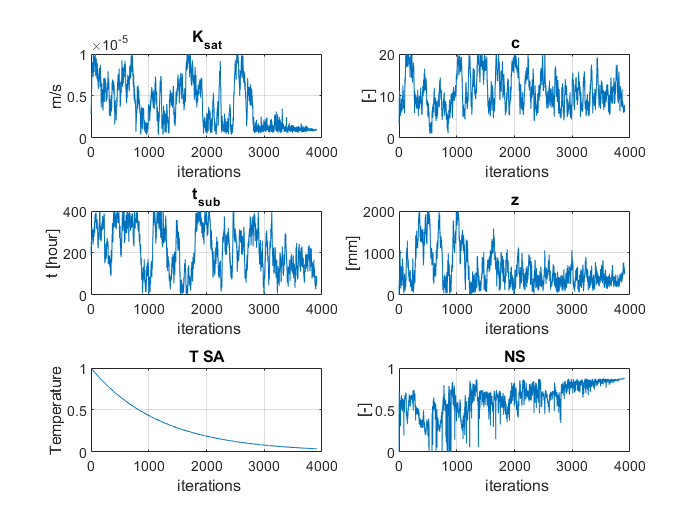

figure

subplot(3,2,1)
plot(Ksat_all)
title("K_{sat}")
xlabel(" iterations")
ylabel("m/s")
grid on

subplot(3,2,2)
plot(1:length(c_all),c_all)
title("c")
xlabel(" iterations")
ylabel("[-]")
grid on

subplot(3,2,3)
plot(1:length(tsub_all),tsub_all)
title("t_{sub}")
xlabel(" iterations")
ylabel("t [hour]")
grid on

subplot(3,2,4)
plot(1:length(z_all),z_all)
title("z")
xlabel(" iterations")
ylabel("[mm]")
grid on

subplot(3,2,5)
plot(1:length(T_SA_all), T_SA_all)
title("T SA")
xlabel(" iterations")
ylabel("Temperature")
grid on

subplot(3,2,6)
plot(1:length(NS_all), NS_all)
ylim([0 1])
title("NS")
xlabel(" iterations")
ylabel("[-]")
grid on

## **Run the hydrological model **

Now that the parameters have been calibreted, the ydrological model can by run. We start with a duration of 6 years. 

n_years = 6;
[Q, R, I, s, L, ET] = GroupD_f_hydromodel(phi, temperature, n_years, P, Ksat, sw, s1, kc, n, Qb, tsup, tsub, A, c, dt, z, doTest);

`2. Plot the time series (6-year-long) of precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the given precipitation).`

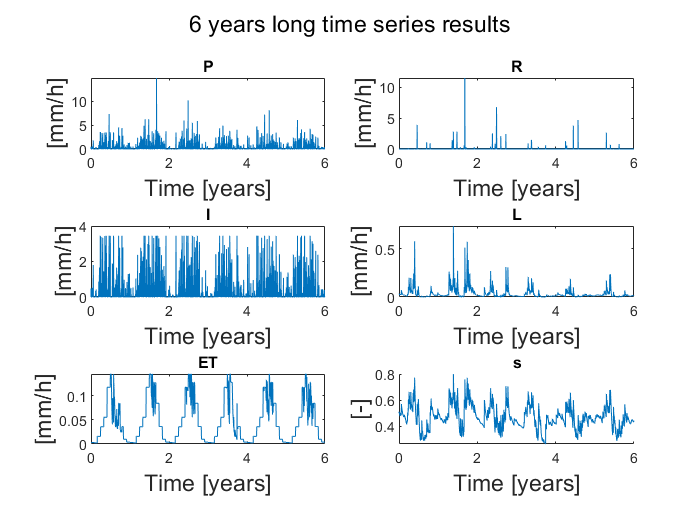

time = 1:length(P);
time = time/24/365;

figure  

subplot(3,2,1)
plot(time, P);
title("P")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,2)
plot(time, R); 
title("R")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,3)
plot(time, I); 
title("I")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,4)
plot(time, L); 
title("L")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,5)
plot(time, ET); 
title("ET")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,6)
plot(time, s(1:end-1));
title("s")
xlabel('Time [years]','fontsize',14)
ylabel('[-]','fontsize',14) 

sgtitle('6 years long time series results')
box off

`3. Plot the time series of observed discharge and of the discharge as simulated by the hydrological model with the best fit parameters`

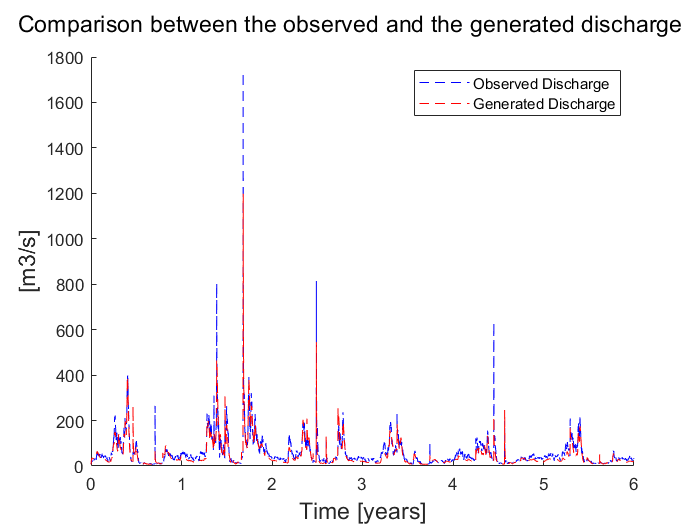

figure 
subplot(1, 1, 1)
plot(time, Q_obs, '--b', time, Q, '--r');
legend('Observed Discharge', 'Generated Discharge')
ylabel('[m3/s]','fontsize',14) 
xlabel('Time [years]','fontsize',14)
box off
sgtitle('Comparison between the observed and the generated discharge')

## **Discharge generation **

The function GroupD_f_discharge generates 100 years of rainfall (at daily timescale) with the parameters (mean daily rainfall depth α and rainfall frequency λ) estimated from the observed precipitation. Then, it runs the calibrated hydrological model forced by the generated rainfall and obtains the discharge time series that will constitute the input of the reservoir. 

For the rest of the exercise, the input discharge is thus Q_gen.

Nyears_gen = 100;               %[years]
Kc = Ksat;                      %[m/s]  hydraulic conductivity (saturated soil) 
[time_gen,Q_gen,R_gen,I_gen,soil_saturation_gen,L_gen,ET_gen,P_gen_mean_monthly] = GroupD_f_discharge(Nyears_gen, P, temperature, kc, dt, n,z,Kc,sw,s1,c,tsup,tsub,A,Qb,phi,doTest);

`5. Plot the comparison between the statistics (mean, standard deviation, α and λ) of the observed and generated precipitation.`

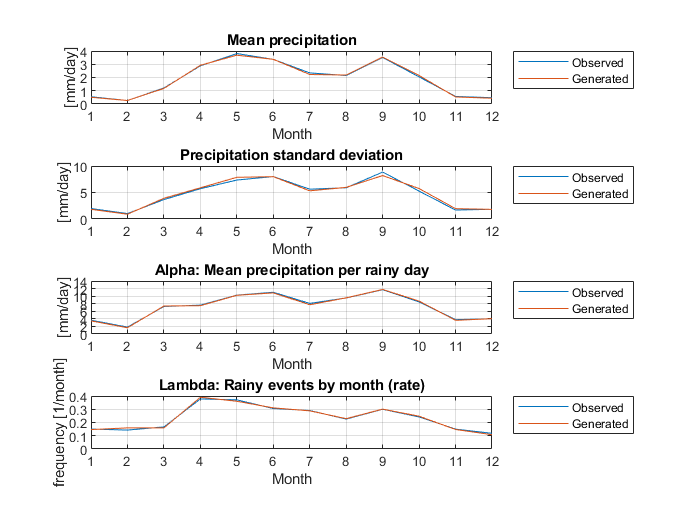

load("Pobs_statistics_parameter.mat");
load("Pgen_statistics_parameter.mat");

figure
subplot(4,1,1)
plot([1:12],Pmean_monthly,[1:12],P_gen_mean_monthly)
xlabel("Month");
ylabel("[mm/day]")
title("Mean precipitation")
legend("Observed","Generated","Location","bestoutside")
grid on
xticks([1:12])
xlim([1,12])
yticks([0:5])

subplot(4,1,2)
plot([1:12],Pstd_monthly,[1:12],Pgenstd_monthly)
xlabel("Month");
ylabel("[mm/day]")
title("Precipitation standard deviation")
legend("Observed","Generated","Location","bestoutside")
grid on
xticks([1:12])
xlim([1,12])

subplot(4,1,3)
plot([1:12],Alpha_monthly,[1:12],Alphagen_monthly)
xlabel("Month");
ylabel("[mm/day]")
title("Alpha: Mean precipitation per rainy day")
legend("Observed","Generated","Location","bestoutside")
grid on
xticks([1:12])
xlim([1,12])
ylim([0,14])
yticks([0:2:14])
subplot(4,1,4)

plot([1:12],Lambda_monthly,[1:12],Lambdagen_monthly)
xlabel("Month");
ylabel("frequency [1/month]")
title("Lambda: Rainy events by month (rate)")
legend("Observed","Generated","Location","bestoutside")
grid on
xticks([1:12])
xlim([1,12])
ylim([0,0.4])
yticks([0:0.1:0.4])

`6. Plot the time series (100-year-long) of generated precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the generated precipitation).`

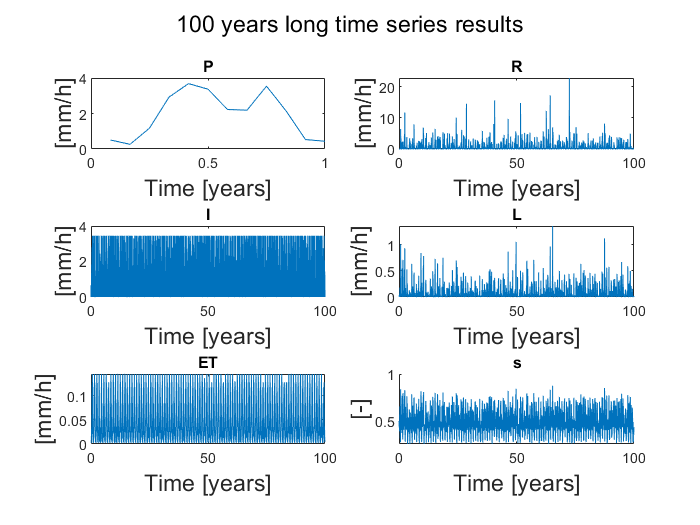

time = 1:length(R_gen);
time = time/24/365;
timeP = 1:length(P_gen_mean_monthly);
timeP = timeP/12;

figure  

subplot(3,2,1)
plot(timeP, P_gen_mean_monthly);
title("P")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,2)
plot(time, R_gen); 
title("R")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,3)
plot(time, I_gen); 
title("I")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,4)
plot(time, L_gen); 
title("L")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,5)
plot(time, ET_gen); 
title("ET")
xlabel('Time [years]','fontsize',14)
ylabel('[mm/h]','fontsize',14) 

subplot(3,2,6)
plot(time, soil_saturation_gen(1:end-1));
title("s")
xlabel('Time [years]','fontsize',14)
ylabel('[-]','fontsize',14) 

sgtitle('100 years long time series results')
box off

`7. Plot the area and the volume rating curves for the given levels.`

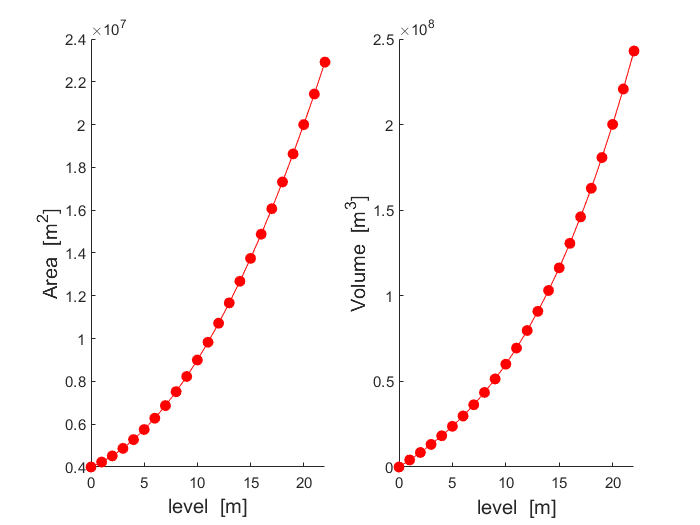

level=area_rating_curve(:,1);         
level=level-level(1);                  
area=area_rating_curve(:,2);     

Volume = zeros(length(level), 1);
for i= 1:length(level)
    Volume(i) = trapz(level(1:i),area(1:i));
end

figure
subplot(1,2,1)
plot(level,area,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)        
ylabel('Area  [m^{2}]','fontsize',12)     
box off
subplot(1,2,2)
plot(level,Volume,'-ro','markerfacecolor','red')
xlabel('level  [m]','fontsize',12)
ylabel('Volume  [m^{3}]','fontsize',12)
box off

`8. Report the minimum flow (discharge that is equalled or exceeded 95% of the time) of the generated discharge and plot the discharge duration curves.`

% Compute the minimum flow target (discharge that is exceeded 95% of the time) of the generated discharge.
Q_sorted = sort(Q_gen); % [m3/s] 
Q347 = Q_sorted(round(length(Q_sorted)/100*5)); % [m3/s]
fprintf('The discharge that is equaled or exceeded 95 %% if the time is Q347 = %g [m^3/s] \n', Q347)

The discharge that is equaled or exceeded 95 % if the time is Q347 = 8.41271 [m^3/s] 


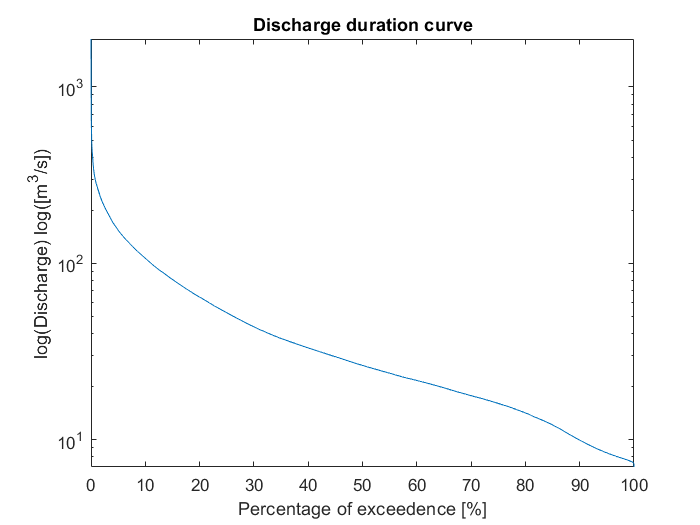

x_series = 1:length(Q_sorted);
x_series = x_series*100/length(Q_sorted);
Q_sorted_descending = flip(Q_sorted);
figure
semilogy(x_series,Q_sorted_descending)
title('Discharge duration curve')
xlabel('Percentage of exceedence [%]')
ylabel('log(Discharge) log([m^3/s])')

## **Hydropower production, Reservoir routing and Flood control **

In order to calculate the hydropower generated, Bernoulli is applied from the reservoir to the tailrace:

                                                                                                                
$$$\frac{P_1}{\gamma} + \frac{v_1^2}{2g} + z_1 = \frac{P_2}{\gamma} + \frac{v_2^2}{2g} + z_2  + h_T + k_L \cdot Q^2$$$


With $k_l
$ regrouping the component head losses and the pipe head loss as: $$k_L = \frac{\frac{f L_{p}}{D} + k_{entry} + k_{exit}}{2gA^2}$$

We find the Darcy-Weisbach friction factor *f* using the Swamee and Jain formula which is an approximation of the Colebrook-White formula that assumes full-flowing in a circular pipe.

In our case, when the turbine functions, it is always with Q = $35 \frac{m^3}{s}$. We hence have a reynolds number of $Re = \frac{vD}{\nu} = \frac{QD}{A\nu} = \frac{4Q}{\pi D\nu} = \frac{4*35}{\pi *3.3*10^{-6} } = 1.35\cdot 10^{7
}$ (turbulent flow)

We hence have $f = \frac{0.25}{log_{10}(\frac{k_s*10^{-3}}{3.7*D} + \frac{5.74}{Re^{0.9}})^2} = 0.0131$              and            $k_L = 0.0044 $

Assuming $z_2 = 0
$, $P_1 = P_2$, $v_1 = v_2 = 0$ and that the difference between the elevation of the empty pool and the tailrace level is constant  $$\Delta z = 75 m$,$ we get that $z_1 =l$ (level in the reservoir named 'l' in code). This yields:

                                                                                                                        
$$h_T = \Delta z + l  - k_L \cdot Q^2$$


The power generated is hence:                                                                                 $P = \eta\gamma Qh_T$

% KNOWN PARAMETERS 
% Of the reservoir 
Cqg = 0.6; % [-] Discharge coefficient for sluice gate 
Cqs = 0.7; % [-] Discharge coefficient for spillway 
Lspill = 140; % [m] Length of the spillway 
p = 19; % [m] level of the spillway crest 
% Of the river 
Qlim = 100; % [m3/s] discharge limit fro floods 
% Of the power plant 
dz = 75; 
eta = 0.73; % [-] Turbine efficiency 
QT = 35; % [m3/s] discharge to the turbine 
delta_h = 75; % [m] difference between the elevation of the empty pool and the tailrace level
lminHU = 7; % [m] min level for hydroelectric production 
D = 3.3; % [m] pipe diameter 
Lp = 1200; % [m] pipe length 
TotWH = 16; % [h] Total working hours
k_s = 0.5; %[mm] sand equivalent roughness
kinematic_viscosity = 1e-06;
Re = (4*QT)/(pi*D*kinematic_viscosity)

Re = 1.3504e+07

f=0.25/(log10((k_s*10^(-3))/(3.7*D) + (5.74)/(Re^0.9)))^2 %friction factor [-] 

f = 0.0131

k_en=0.5; %entrance head loss coefficient [-]
k_ex=1; %exit head loss coefficient [-]
g=9.80; %gravity acceleration [m/s^2]
gamma=9800; %water specific weight [N/m^3]  (approximation at Earth ambiant temperatures)
A=pi*(D/2)^2; %Area of pipe
k_L=(f*Lp/D+k_en+k_ex)*1/(2*g*A^2)

k_L = 0.0044


% h_min_P = 610 %[masl]
% h_min = 600 % [masl]
% h_max = 620 % [masl]
% h_spill = 618 % [masl]

% VARIABLE INITIALIZATION
nyears = 100; % [y] number of years 
ndays = nyears*365; % [d] number of days
nt = ndays * 24; % [h] nb of total hours ie timesteps
Qout = zeros(nt, 19-9+1);
QHU = zeros(nt, 19-9+1);
V = zeros(nt, 19-9+1);
l = zeros(nt, 19-9+1);
Qg = zeros(nt, 19-9+1);
annual_EnergyT = zeros(nyears, 19-9+1);
annual_flood_p = zeros(nyears, 19-9+1);

% Assume a maximum level for HU (e.g. l max,HU = 15 m).
% Repeat for different values of the maximum level for HU (from 9 to 19 m, step equal or lower to 1 m)
lmaxHU = 0;
for lmaxHU_val = 9:19
    lmaxHU = lmaxHU + 1;
    VmaxHU = Volume(find(level==lmaxHU));
    for y=1:nyears
        EnergyT = zeros(365*24);
        flood_p = zeros(365*24);        
        i = 1;
        for d=1:365
            for h = 1:24
                t = (y-1)*365*24 + (d-1)*24 + h;
                % DETERMINATION OF WETHER THE TURBINES ARE WORKING OR NOT 
                % If at midnight the level in the reservoir is above the minimum level for hydroelectrical use, 
                % the plant will work during that day, otherwise it will not
                turb_day = l((y-1)*365*24 + (d-1)*24+1, lmaxHU) > lminHU;  
                % The turbines work between 06:00 and 22:00 
                turb = turb_day && 6<h && h<22; 
                if ~turb  % If turbines do not work, the turbine flow is null 
                    QHU(t, lmaxHU) = 0; 
                else % else, it is the constant turbine flow
                    QHU(t, lmaxHU) = QT; 
                end
    
                % RESERVOIR ROUTING WITH FLOOD CONTROL 
                if t==1
                    l(t, lmaxHU) = lmaxHU_val;                    
                    V(t, lmaxHU) = VmaxHU;
                    tmp = V(t, lmaxHU) + abs(Q(t) - QHU(t, lmaxHU)) - VmaxHU;
                    Qg(t, lmaxHU) = max(Q347, min(Qlim, tmp));
                    if l(t, lmaxHU) <= p 
                        Qout(t, lmaxHU) = Qg(t, lmaxHU); %Cqg*Asg*sqrt(2*g*l(t, lmaxHU));
                    else 
                        Qout(t, lmaxHU) =Qg(t, lmaxHU) + Cqs*L*sqrt(2*g*(l(t, lmaxHU)-p)^3);
                    end 
                    dV = (Q_gen(t) - Qout(t, lmaxHU) - QHU(t, lmaxHU))*60*60; % dt = 1 [h] = 1*60*60 [s] and Q in [m3/s]  
                    V(t+1, lmaxHU) = V(t, lmaxHU) + dV;
                    % Turbine power
                    PT = 0;
                    
                else 
                    if  V(t, lmaxHU)<0
                        t0 = t
                        l0 = l(t-1, lmaxHU)
                        QHU0 = QHU(t-1, lmaxHU)
                        vol0 = V(t-1, lmaxHU)
                        dV001 = dV
                        vol1 = V(t, lmaxHU)
                    end
                    l(t, lmaxHU) = level_volume(Volume,  level, V(t, lmaxHU));
                    tmp = V(t-1, lmaxHU) + abs(Q_gen(t) - QHU(t, lmaxHU)) - VmaxHU;
                    Qg(t, lmaxHU) = max(Q347, min(Qlim, tmp)); 
                    if l(t, lmaxHU) <= p 
                        Qout(t, lmaxHU) = Qg(t, lmaxHU); %Cqg*Asg*sqrt(2*g*l);
                    else 
                        Qout(t, lmaxHU) = Qg(t, lmaxHU) + Cqs*Lspill*sqrt(2*g*(l(t, lmaxHU)-p).^3);
                    end 
                    dV = (Q_gen(t) - Qout(t, lmaxHU) - QHU(t, lmaxHU))*dt*60*60; % dt = 1 [h] = 1*60*60 [s] and Q in [m3/s] 
                    if t+1 <= nyears*365*24 
                        V(t+1, lmaxHU) = V(t, lmaxHU) + dV;
                        if V(t+1, lmaxHU)<0
                            V(t+1, lmaxHU)=0;
                        end                    
                    end
                    
                    
                    % TURBINE POWER
                    % Account for frictional head losses along the pipe, entrance head loss (half of the kinematic term) and exit head loss (one kinematic term)   
                    hT = dz + l(t, lmaxHU) - k_L*QHU(t, lmaxHU)^2; %[m] net head of turbine
                    PT = eta*gamma*QHU(t, lmaxHU)*hT/1000; %[kW] = [kg m2 s-3] = [kJ s-1]
                end 
                
                % Energy production
                EnergyT(i) = PT*dt; %[kwh]
                i = i+1;
                
                % PROBABILITY THAT QOUT EXCEEDS 100 M3/S. For numerical reasons, the conditions should read Qout > 101 m3/s.
                flood_p(i) = Qout(t, lmaxHU) > 101;  
            end            
        end 
        % ANNUAL MEANS
        annual_EnergyT(y, lmaxHU) = sum(EnergyT, 'all'); % [kWh]
        annual_flood_p(y, lmaxHU) = numel(flood_p(flood_p > 0))/numel(flood_p);
    end 
    fprintf('Computations for max height of %g meters done\n', lmaxHU_val)
end 

Computations for max height of 9 meters done
Computations for max height of 10 meters done
Computations for max height of 11 meters done
Computations for max height of 12 meters done
Computations for max height of 13 meters done
Computations for max height of 14 meters done
Computations for max height of 15 meters done
Computations for max height of 16 meters done
Computations for max height of 17 meters done
Computations for max height of 18 meters done
Computations for max height of 19 meters done


avg_annual_EnergyT =  mean(annual_EnergyT,1);
avg_annual_flood_p =  mean(annual_flood_p,1);

`9. For a maximum level for hydroelectric use of 15 m, plot the time series (100 years long) of input discharge, output discharge, volume within the reservoir and level.`

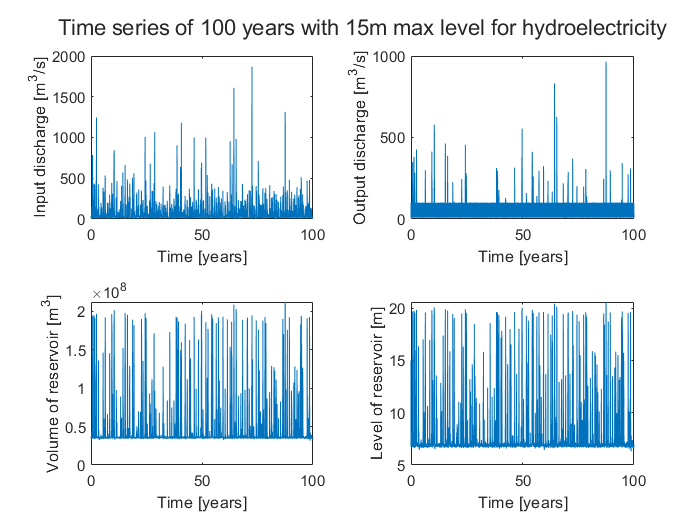

time = 1:length(Q_gen);
time = time/24/365;

t = tiledlayout(2,2);

nexttile
plot(time,Q_gen)
ylabel('Input discharge [m^3/s]')
xlabel('Time [years]')

nexttile
plot(time,Qout(:, 7))
ylabel('Output discharge [m^3/s]')
xlabel('Time [years]')

nexttile
plot(time, V(:, 7))
ylabel('Volume of reservoir [m^3]')
xlabel('Time [years]')

nexttile
plot(time,l(:, 7))
ylabel('Level of reservoir [m]')
xlabel('Time [years]')
sgtitle('Time series of 100 years with 15m max level for hydroelectricity')
tiledlayout(4, 1);

`10. Plot the average annual energy production in [GWh] and the probability that Q out exceeds Q lim for different values of the maximum level for hydroelectrical use.`

`On the plot it is clear that increasing the maximum height for hydroelectric prodction increases significantly the energy production and the probability of floods. This means that a trade off between the security and revenue must be found.   `

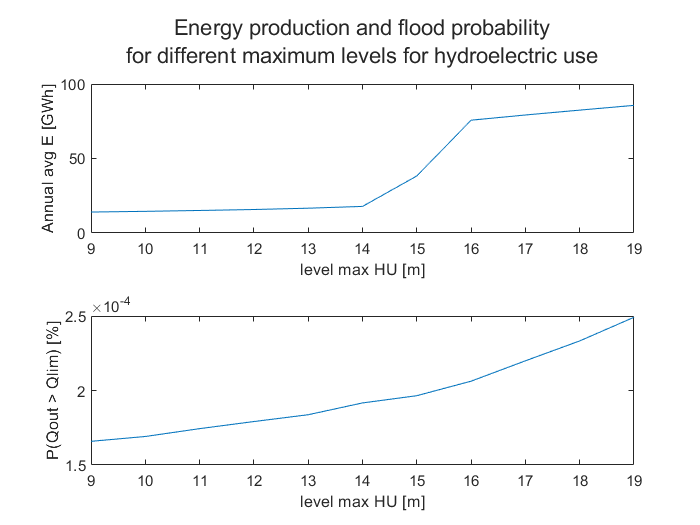

lmax = 9:19;
t = tiledlayout(2,1);
nexttile
plot(lmax, avg_annual_EnergyT.*10^-6)
ylabel('Annual avg E [GWh]')
xlabel('level max HU [m]')
%title('Average annual energy production for different maximum levels for hydroelectric use') 

nexttile
plot(lmax, avg_annual_flood_p*100)
ylabel('P(Qout > Qlim) [%]')
xlabel('level max HU [m]')
%title('Probability that Qout exceeds Qlim for different maximum levels for hydroelectric use') 
sgtitle({'Energy production and flood probability' , 'for different maximum levels for hydroelectric use'})
t = tiledlayout(2,1);

`11. Plot the Pareto front of average annual energy production in [GWh] vs the probability that Q out exceeds Q lim computed from different values of the maximum level for hydroelectrical use.`

`The relationship between the flood probability and ernergy production is contains three parts with two disctinct trends. Indeed, for very high or very low energy production, the evolution of the flood probability is very steep (lower for lower ernergy production). For the middle values, the slope is much smaller. This means that production 20GWh or 80GWh has almost the same flood risk whereas 90GWh is much riskier than 80GWh.      `

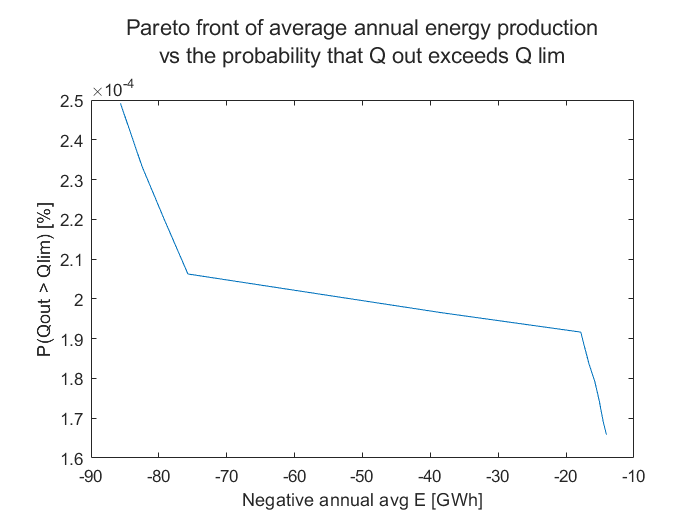

t = tiledlayout(1,1);
nexttile
plot(-avg_annual_EnergyT*10^-6, avg_annual_flood_p*100)
xlabel('Negative annual avg E [GWh]')
ylabel('P(Qout > Qlim) [%]')
sgtitle({'Pareto front of average annual energy production', 'vs the probability that Q out exceeds Q lim'}) 